url = 'https://gml.noaa.gov/webdata/ccgg/trends/co2/co2_mm_mlo.csv';
opts = detectImportOptions(url, 'Delimiter', ',', 'CommentStyle', '#');
T = readtable(url, opts);    % Lee directo desde la URL

head(T)

    year    month    decimalDate    average    deseasonalized    ndays    sdev      unc 
    ____    _____    ___________    _______    ______________    _____    _____    _____

    1958      3        1958.2       315.71         314.44         -1      -9.99    -0.99
    1958      4        1958.3       317.45         315.16         -1      -9.99    -0.99
    1958      5        1958.4       317.51         314.69         -1      -9.99    -0.99
    1958      6        1958.5       317.27         315.15         -1      -9.99    -0.99
    1958      7        1958.5       315.87          315.2         -1      -9.99    -0.99
    1958      8        1958.6       314.93         316.21         -1      -9.99    -0.99
    1958      9

Analizando serie de tiempo

T.Fecha = datetime(T.year, T.month, 1)

T = 810×9 table
    year    month    decimalDate    average    deseasonalized    ndays    sdev      unc        Fecha   
    ____    _____    ___________    _______    ______________    _____    _____    _____    ___________

    1958      3        1958.2       315.71         314.44         -1      -9.99    -0.99    01-Mar-1958
    1958      4        1958.3       317.45         315.16         -1      -9.99    -0.99    01-Apr-1958
    1958      5        1958.4       317.51         314.69         -1      -9.99    -0.99    01-May-1958
    1958      6        1958.5       317.27         315.15         -1      -9.99    -0.99    01-Jun-1958
    1958      7        1958.5       315.87          3

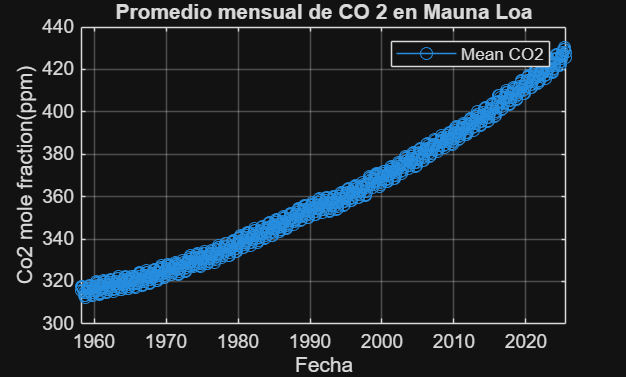


% Graficar los promedios mensuales
figure;
plot(T.Fecha, T.average, '-o', 'DisplayName', 'Mean CO2');

% Añadir etiquetas y leyenda
xlabel('Fecha');
ylabel('Co2 mole fraction(ppm)');
title('Promedio mensual de CO 2 en Mauna Loa');
legend show;
grid on;

Sacando pendiente

tiempo_num = datenum(T.Fecha);
tiempo_num_2 = 1:length(T.Fecha);


model_lineal = polyfit(tiempo_num, T.average, 1)

model_lineal = 1.0e+03 *

    0.0000   -2.9370


model_lineal_2 = polyfit(tiempo_num_2, T.average, 1)

model_lineal_2 =     0.1380  304.4244


modelo_cuadratico_1 = polyfit(tiempo_num, T.average, 2)

modelo_cuadratico_1 = 1.0e+04 *

    0.0000   -0.0000    5.0540


modelo_cuadratico_2 = polyfit(tiempo_num_2, T.average, 2)

modelo_cuadratico_2 =     0.0001    0.0620  314.6989




output_model_1 = polyval(model_lineal, tiempo_num);
output_model_2 = polyval(model_lineal_2, tiempo_num_2);
output_model_cuad_1 = polyval(modelo_cuadratico_1, tiempo_num);
output_model_cuad_2 = polyval(modelo_cuadratico_2, tiempo_num_2);


Graficando

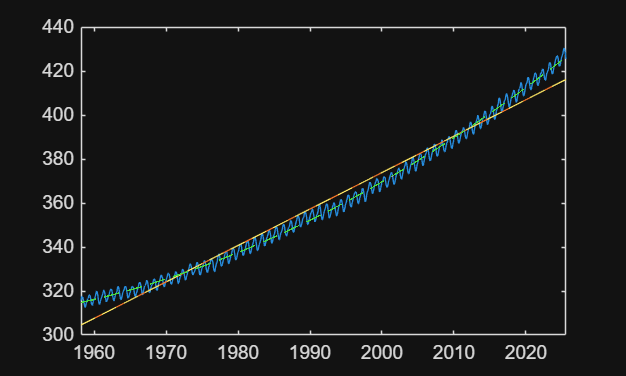

figure;
plot(T.Fecha, T.average)
hold on;
plot(T.Fecha, output_model_1)
hold on;
plot(T.Fecha, output_model_2, '--', 'DisplayName', 'Modelo Lineal 2');
hold on;
plot(T.Fecha, output_model_cuad_1, '--', 'DisplayName', 'Modelo Cuadrático 1');
hold on;
plot(T.Fecha, output_model_cuad_2, '--', 'DisplayName', 'Modelo Cuadrático 2');
hold off;

   Removiendo tendencias

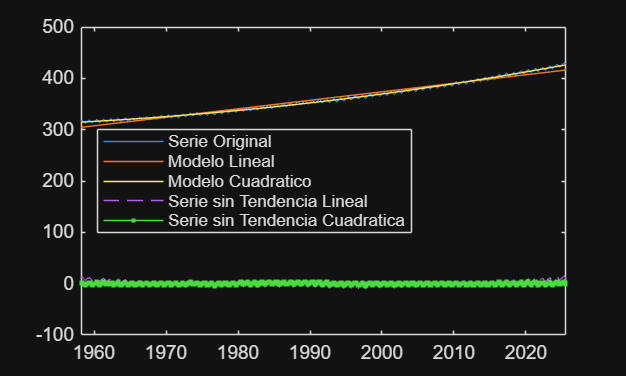


serie_sin_tendencia_lineal = T.average - output_model_1;
serie_sin_tendencia_cuadratica = T.average - output_model_cuad_1;


figure;
plot(T.Fecha, T.average, "DisplayName", "Serie Original")
hold on;
plot(T.Fecha, output_model_1, "DisplayName", "Modelo Lineal")
hold on;
plot(T.Fecha, output_model_cuad_1, "DisplayName", "Modelo Cuadratico")
hold on;
plot(T.Fecha, serie_sin_tendencia_lineal, '--', 'DisplayName', 'Serie sin Tendencia Lineal');
hold on;
plot(T.Fecha, serie_sin_tendencia_cuadratica, '.-', 'DisplayName', 'Serie sin Tendencia Cuadratica');
legend('Location',"west")
hold off;